Входные параметры

close all;
clear variables;

#### 1.1 Исходные данные

% параметры волны
f = 400*10^6;
c = 3*10^8;
lambda = 10000; % 0.75 м %%% убрать 
phi_grad = 180;

% константы
k = 2*pi;
eta = 120*pi;
gamma = 1.781072417990;

#### 1.3. Расчет координат точек исходной фигуры

% точки оснвого конутра
pl_x(1) = 0;
pl_z(1) = 0;
pl_x(2) = 0;
pl_z(2) = 11000;
pl_x(3) = 11000;
pl_z(3) = 11000;
pl_x(4) = 11000;
pl_z(4) = 0;

% точки вспомогат контура
d_as = 100;
pli_x(1) = d_as;
pli_z(1) = 0;
pli_x(2) = d_as;
pli_z(2) = pl_z(2) - d_as;
pli_x(3) = pl_x(3) - d_as;
pli_z(3) = pl_z(3) - d_as;
pli_x(4) = pl_x(4) - d_as;
pli_z(4) = 0;

% в длинах волн
pl_x = pl_x/lambda;
pl_z = pl_z/lambda;
pli_x = pli_x/lambda;
pli_z = pli_z/lambda;

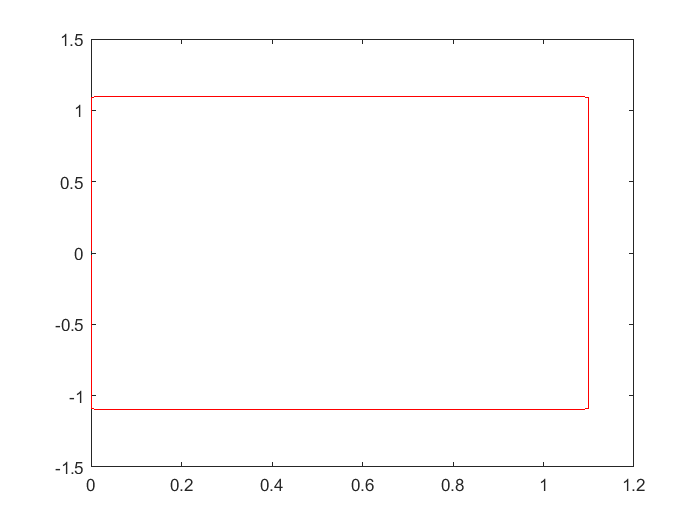

N_i = 40;
N_l = 40;

step1 = pl_z(2)/N_l;
step2 = pl_x(3)/N_l;
for i = 1 : N_l
    x1(i) = 0;
    z1(i) = (i-0.5)*step1;
    x2(i) = (i-0.5)*step2;
    z2(i) = pl_z(2);
    x3(i) = pl_x(3);
    z3(i) = pl_z(3) - (i-0.5)*step1;
    
    dx1(i) = step1;
    dx2(i) = step2;
    dx3(i) = step1;
    
    tx1(i) = 0;
    tz1(i) = 1;
    tx2(i) = 1;
    tz2(i) = 0;
    tx3(i) = 0;
    tz3(i) = -1;
end
x_midle = horzcat(x1,x2,x3);
x_midle = horzcat(x_midle, flip(x_midle));
z_midle = horzcat(z1,z2,z3);
z_midle = horzcat(z_midle, flip(-z_midle));
tx = horzcat(tx1,tx2,tx3,tx3,-tx2,tx1);
tz = horzcat(tz1,tz2,tz3,tz3,-tz2,tz1);

plot(x_midle, z_midle, 'r')

step1_i = pli_z(2)/N_i;
step2_i = 9600/lambda/N_i;
for i = 1 : N_i
    x1_i(i) = pli_x(1);
    z1_i(i) = (i-0.5)*step1_i;
    x2_i(i) = pli_x(2) + (i-0.5)*step2_i;
    z2_i(i) = pli_z(2);
    x3_i(i) = pli_x(3);
    z3_i(i) = pli_z(3) - (i-0.5)*step1_i;
    
end
x_midle_i = horzcat(x1_i,x2_i,x3_i);
x_midle_i = horzcat(x_midle_i, flip(x_midle_i));
z_midle_i = horzcat(z1_i,z2_i,z3_i)

z_midle_i =     0.0136    0.0409    0.0681    0.0954    0.1226    0.1499    0.1771    0.2044    0.2316    0.2589    0.2861    0.3134    0.3406    0.3679    0.3951    0.4224    0.4496    0.4769    0.5041    0.5314    0.5586    0.5859    0.6131    0.6404    0.6676    0.6949    0.7221    0.7494    0.7766    0.8039    0.8311    0.8584    0.8856    0.9129    0.9401    0.9674    0.9946    1.0219    1.0491    1.0764    1.0900    1.0900    1.0900    1.0900    1.0900    1.0900    1.0900    1.0900    1.0900    1.0900


z_midle_i = horzcat(z_midle_i, flip(-z_midle_i));

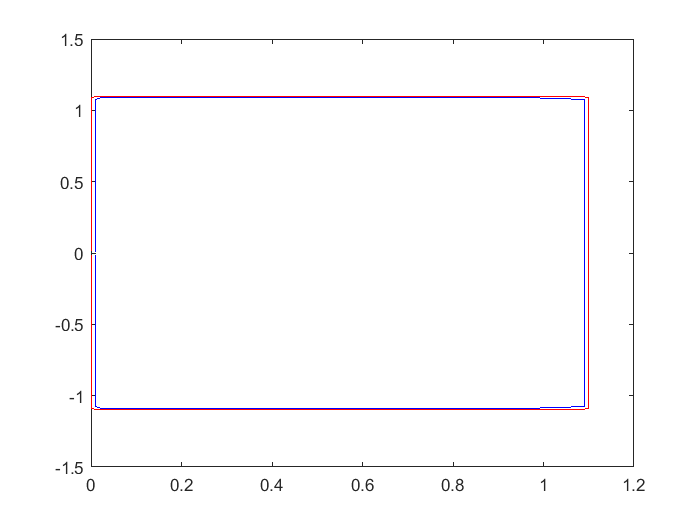

plot(x_midle, z_midle, 'r', x_midle_i, z_midle_i, 'b')


% количество точек
N_i_all = 2*3*N_i;
N_l_all = 2*3*N_l;

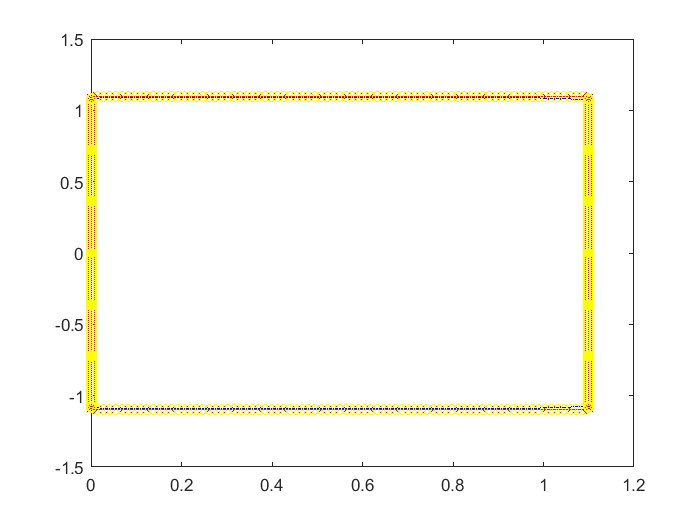

N_DE = 2*N_l;

step1_DE = pl_z(2)/N_DE;
step2_DE = pl_x(3)/N_DE;
for i = 1 : N_DE-1
    x1_DE(i) = 0;
    z1_DE(i) = i*step1_DE;
    x2_DE(i) = i*step2_DE;
    z2_DE(i) = pl_z(2);
    x3_DE(i) = pl_x(3);
    z3_DE(i) = pl_z(3) - i*step1_DE;

    tx1_DE(i) = 0;
    tz1_DE(i) = 1;
    tx2_DE(i) = 1;
    tz2_DE(i) = 0;
    tx3_DE(i) = 0;
    tz3_DE(i) = -1;
end

% plot(x1_DE, z1_DE, 'rx')

x_midle_DE = horzcat(x1_DE,x2_DE,x3_DE);
x_midle_DE = horzcat(x_midle_DE, flip(x_midle_DE));
z_midle_DE = horzcat(z1_DE,z2_DE,z3_DE);
z_midle_DE = horzcat(z_midle_DE, flip(-z_midle_DE));
tx_DE = horzcat(tx1_DE,tx2_DE,tx3_DE, tx3_DE, -tx2_DE, tx1_DE);
tz_DE = horzcat(tz1_DE,tz2_DE,tz3_DE, tz3_DE, -tz2_DE, tz1_DE);

hold on
plot(x_midle, z_midle, 'rx', x_midle_i, z_midle_i, 'b')
plot(x_midle_DE, z_midle_DE, 'yo')
hold off


% количество точек невязки
N_DE_all = 2*3*(N_DE-1);

#### 1.5. Расчет координат излучателя

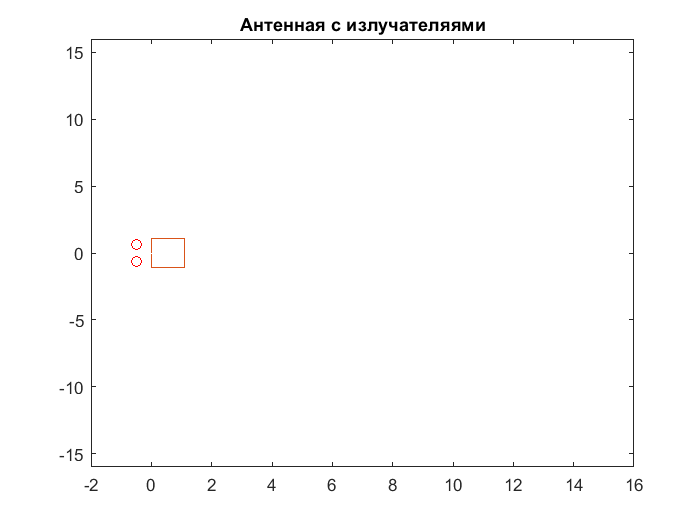

% паарметры расположения
l_antenn = 5000/lambda; %%% убрать
h_antenn = 1/2; %%% убрать

% координаты самого излучателя
x1_antenn = - h_antenn;
z1_antenn = pl_x(3) - l_antenn;

x2_antenn = x1_antenn;
z2_antenn = -z1_antenn;

plot(x_midle, z_midle, x_midle_i, z_midle_i, x1_antenn, z1_antenn, 'ro', x2_antenn, z2_antenn, 'ro');
xlim([-2.00 16.00])
ylim([-16 16.0])
title('Антенная с излучателяями')

#### 5.1. Падающее поле

% излучаель создает магнитное поле 
Ei = double(zeros(N_l,1));
% падающее поле 
for m = 1 : N_l_all
    xm = x_midle(m);
    zm = z_midle(m);
    txm = tx(m);
    tzm = tz(m);
    
    % растояния 
    r1 = ((xm-x1_antenn)^2 + (zm-z1_antenn)^2);
    r2 = ((xm-x2_antenn)^2 + (zm-z2_antenn)^2);
    
    % Падающее магнитное поле
    Eix = -(zm-z1_antenn)*besselh(1,1,k*r1)/r1...
          -(zm-z2_antenn)*besselh(1,1,k*r2)/r2;
    Eiz = +(xm-x1_antenn)*besselh(1,1,k*r1)/r1...
          +(xm-x2_antenn)*besselh(1,1,k*r2)/r2;
    % Касательное электрическое поле
    Ei(m) = Eix*txm + Eiz*tzm;
end  

#### 5.1. Падающее поле

% % падающее поле ПЛОСКИЙ ФРОН
% 
% % излучаель создает магнитное поле 
% Ei = double(zeros(N_l,1));
% % падающее поле 
% for m = 1 : N_l_all
%     xm = x_midle(m);
%     zm = z_midle(m);
%     txm = tx(m);
%     tzm = tz(m);
%     cx = -1i*k*cosd(phi_grad);
%     cz = -1i*k*sind(phi_grad);
%     
%     % Падающее магнитное поле
%     Eix = -sind(phi_grad)*exp(cx*xm+cz*zm);% падающее поле X
%     Eiz = +cosd(phi_grad)*exp(cx*xm+cz*zm);% падающее поле Z
%     % Касательное электрическое поле
%     Ei(m) = Eix*txm + Eiz*tzm;
% end  

#### Сам алгоритм MAS

% Hs = zeros(N,N);
% Es = double(zeros(N_i,N_l));
for m = 1 : N_l_all
    xm = x_midle(m);
    zm = z_midle(m);
    txm = tx(m);
    tzm = tz(m);
    
    %пробегаемся по всем точкам ВИ
    for n = 1 : N_i_all
        xn = x_midle_i(n);
        zn = z_midle_i(n);
        
        xmn = xm - xn;
        zmn = zm - zn;
        rmn = sqrt(xmn^2 + zmn^2);
                
        Ex = -zmn*besselh(1,1,k*rmn)/rmn;
        Ez = +xmn*besselh(1,1,k*rmn)/rmn;
        Es(m,n) = Ex*txm + Ez*tzm;
    end
end

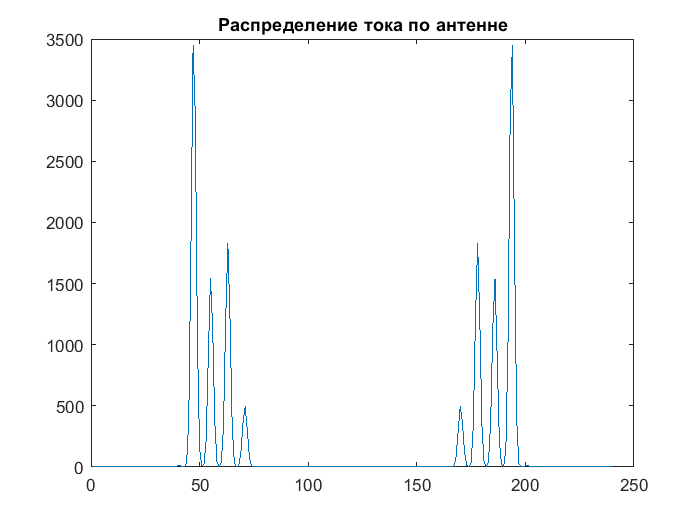

% расчеток токов ВИ 
I=Es\Ei;

plot(1:length(I), abs(I));
title("Распределение тока по антенне")

#### НЕВЯЗКА цилиндр фронт

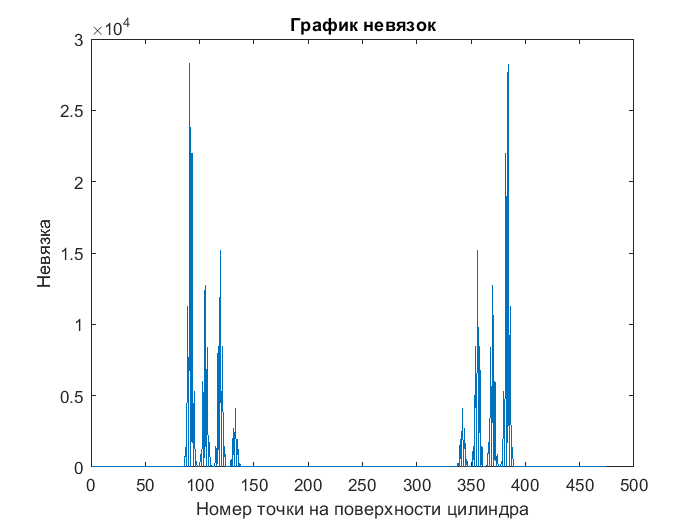

for m = 1 : N_DE_all  
    xm = x_midle_DE(m);
    zm = z_midle_DE(m);
    txm = tx_DE(m);
    tzm = tz_DE(m);
    
    E_DE_sum = 0;    
    for n = 1 : N_i_all
        xn = x_midle_i(n);
        zn = z_midle_i(n);    
                  
        % токи ВИ
        xmn = xm - xn;
        zmn = zm - zn;
        rmn = sqrt(xmn^2 + zmn^2);
            
        Ex = - zmn*besselh(1,1,k*rmn)/rmn;
        Ez = + xmn*besselh(1,1,k*rmn)/rmn;
        Es_DE = Ex*txm + Ez*tzm;
          
        % суммарное поле от ВИ в точке m
        E_DE_sum = E_DE_sum + I(n)*Es_DE;
        
    end
    
    % Падающее магнитное поле
    % растояния 
    r1 = ((xm-x1_antenn)^2 + (zm-z1_antenn)^2);
    r2 = ((xm-x2_antenn)^2 + (zm-z2_antenn)^2);
    
    Eix = -(zm-z1_antenn)*besselh(1,1,k*r1)/r1...
          -(zm-z2_antenn)*besselh(1,1,k*r2)/r2;
    Eiz = +(xm-x1_antenn)*besselh(1,1,k*r1)/r1...
          +(xm-x2_antenn)*besselh(1,1,k*r2)/r2;
    % Касательное электрическое поле
    Ei_DE = Eix*txm + Eiz*tzm;
     
    % cам расчет невязки
    dE(m,1) =  abs(Ei_DE - E_DE_sum);
end    
    
% график для невязки
figure;
plot(1:length(dE),dE);
title('График невязок'); 
xlabel('Номер точки на поверхности цилиндра'); 
ylabel('Невязка');

#### НЕВЯЗКА плоский фронт

% 
% for m = 1 : N_DE_all  
%     xm = x_midle_DE(m);
%     zm = z_midle_DE(m);
%     txm = tx_DE(m);
%     tzm = tz_DE(m);
%     
%     E_DE_sum = 0;    
%     for n = 1 : N_i_all
%         xn = x_midle_i(n);
%         zn = z_midle_i(n);    
%                   
%         % токи ВИ
%         xmn = xm - xn;
%         zmn = zm - zn;
%         rmn = sqrt(xmn^2 + zmn^2);
%             
%         Ex = + 1i*zmn*besselh(1,1,k*rmn)/rmn;
%         Ez = - 1i*xmn*besselh(1,1,k*rmn)/rmn;
%         Es_DE = Ex*txm + Ez*tzm;
%           
%         % суммарное поле от ВИ в точке m
%         E_DE_sum = E_DE_sum + I(n)*Es_DE;
%         
%     end
%     
%     % Падающее магнитное поле
%     cx = -1i*k*cosd(phi_grad);
%     cz = -1i*k*sind(phi_grad);
%     
%     % Падающее магнитное поле
%     Eix = +1i*sind(phi_grad)*exp(cx*xm+cz*zm);% падающее поле X
%     Eiz = -1i*cosd(phi_grad)*exp(cx*xm+cz*zm);% падающее поле Z
%     % Касательное электрическое поле
%     Ei_DE = Eix*txm + Eiz*tzm;
%      
%     % cам расчет невязки
%     dE(m,1) =  abs(Ei_DE - E_DE_sum);
% end    
%     
% % график для невязки
% figure;
% plot(1:length(dE),dE);
% title('График невязок'); 
% xlabel('Номер точки на поверхности цилиндра'); 
% ylabel('Невязка');
